## 1. Ecuatii neliniare in $\Re$


$$\textrm{fie}\;\textrm{ecuatia}\;\cos \left(x\right)=x;$$



$$\begin{array}{l}
\Rightarrow f\left(x\right)=\cos \left(x\right)-x;\\
f^{\prime } \left(x\right)=-\sin \left(x\right)-1;
\end{array}$$


f = @(x) cos(x) - x;
df = @(x) -sin(x) - 1;

### 1.1. Metoda lui Newton

Metoda lui Newton

[xsol,ni] = NewtonSist(f,df,pi/4,1e-6)

xsol = 0.7391

ni = 3

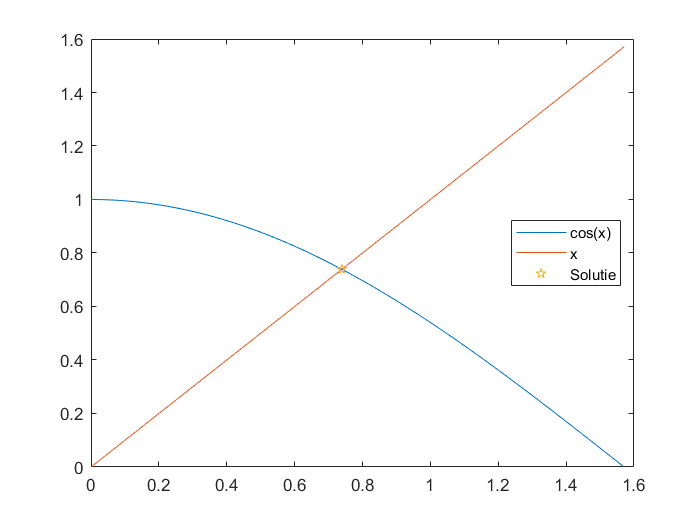

t = linspace(0,pi/2,1000);
plot(t,cos(t), t, t, xsol, cos(xsol),'p')
legend('cos(x)','x','Solutie', 'Location',"best");

### 1.2. Metoda secantei

Implementare

[xsol,ni] = SecantaEc(f,0.5, pi/4,1e-6,1000)

xsol = 0.7391

ni = 6

t = linspace(0,pi/2,1000);
plot(t,cos(t), t, t, xsol, cos(xsol),'p')
legend('cos(x)','x','Solutie', 'Location',"best");

### 1.3. Metoda lui Steffensen

Implementare


$$\textrm{fie}\;\textrm{ecutia}{\;x}^3 +{4x}^2 -10=0\Leftrightarrow x^2 \left(x+4\right)=10\Leftrightarrow x^2 =\frac{10}{x+4}\Leftrightarrow x=\sqrt{\frac{10}{x+4}}\Rightarrow g\left(x\right)=\sqrt{\frac{10}{x+4}}\;,g\left(x\right)=x$$
  

g = @(x) sqrt(10./(x+4));
ec = @(x) (x.^3 + 4.*x.^2 - 10);
[xsol,ni] = SteffensenEc(g,1.5,1e-6,100)

xsol = 1.3652

ni = 4

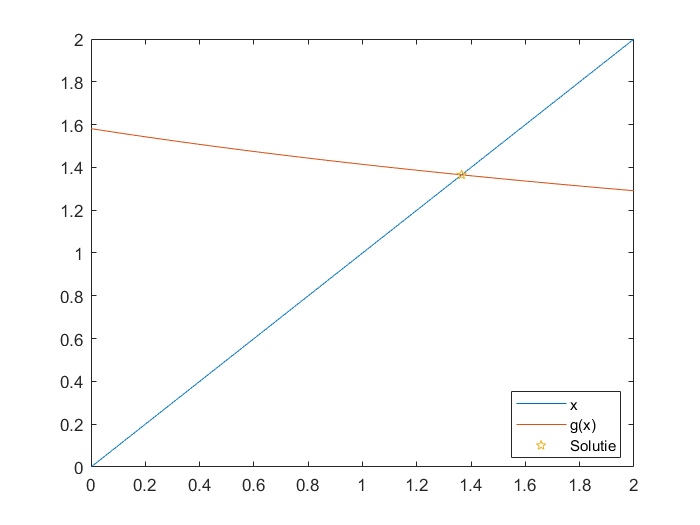

t = linspace(0,2,1000);
plot( t, t, t, g(t), xsol, g(xsol),'p')
legend('x', 'g(x)','Solutie', 'Location',"best");

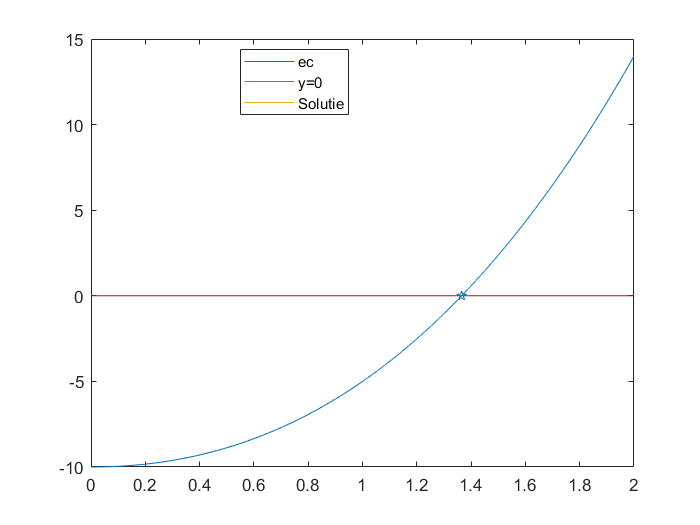

plot(t,ec(t), t, zeros(length(t)), xsol, ec(xsol),'p');
legend('ec','y=0','Solutie', 'Location',"best");

## 1.5. Metoda aproximatiilor succesive

Implementare

[xsol,ni] = metoda_aproximatii_succesive(f,pi/4, 1e-3)

Error using laborator12>metoda_aproximatii_succesive (line 103)
iteration number exceeded

t = linspace(0,pi/2,1000);
plot(t,cos(t), t, t, xsol, cos(xsol),'p')
legend('cos(x)','x','Solutie', 'Location',"best");

## 2. Sisteme de ecuatii neliniare

### 2.1. Metoda lui Newton

Implementare

### 2.4 Probleme

1. 


$$\left\lbrace \begin{array}{ll}
x^2 \;{+\;y}^2 =1 & \\
x^3 -y=0 & 
\end{array}\right.$$


f = @(x) [  x(1).^2 + x(2).^2 - 1   ;
            x(1).^3 - x(2)          ];
        
fJacob = @(x) [2.*x(1), 2.*x(2); 3.*(x(1).^2), -1];
p0 = [0.5, 1.12]';
[z,ni] = NewtonSist(f,fJacob, p0,1e-8)
f(z)
norm(f(z) - zeros(length(z)))

2. 


$$\begin{cases}
9x^2 + 36y^2 + 4z^2 - 36 = 0 \\
x^2 - 2y^2 - 20z = 0 \\
x^2 - y^2 + z^2 = 0
\end{cases}$$


clear all
clc
f = @(x) [ double(9*(x(1)^2) + 36*(x(2)^2)+ 4*(x(3)^2) - 36) ; 
           double(x(1)^2 - 2*(x(2)^2) -20*x(3))              ;
           double(x(1)^2 - x(2)^2 + x(3)^2)                  ];
fJacob = @(x) [ 18*x(1),   72*x(2),   8*x(3)    ;
                 2*x(1),  -4*x(2), -20          ;
                 2*x(1),  -2*x(2),  2*x(3)      ];

p0 = [1, 1, 0]';
[z,ni] = NewtonSist(f,fJacob, p0,1e-8)
f(z)
norm(f(z) - zeros(length(z)))

function [p,ni]=NewtonSist(f,fd,p0,ea,er,nmax)
    if nargin < 6, nmax=50; end
    if nargin < 5, er=0; end
    if nargin < 4, ea=1e-3; end
    p0=p0(:);
    for k=1:nmax
        p=p0-fd(p0)\f(p0);
        if norm(p-p0,inf)<ea+er*norm(p,inf)
            ni=k;
            return
        end
        p0=p;
    end
    error('S-a depasit numarul maxim de iteratii');
end

function [p,ni]=SecantaEc(f,p0,p1, tol, N0)
    if nargin<5, N0=50; end
    if nargin<4, tol=1e-3; end
 
    q0 = f(p0);
    for i=2:N0
        q1 = f(p1);
        p = p1 - q1*(p1-p0)/(q1-q0);
        if abs(p-p0)<tol
            ni=i;
            return
        end
        p0 = p1; q0 = q1; p1 = p;
    end
    error('s-a depasit numarul maxim de iteratii')
end

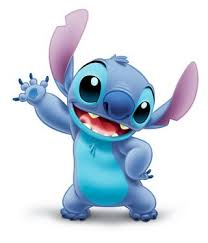

function [p,ni] = SteffensenEc(g,p0, tol, N0)
    if nargin<4, N0=50; end
    if nargin<3, tol=1e-3; end
 
    for i=2:N0
        p1 = g(p0);
        p2 = g(p1);
        p = p0 - ((p1-p0)^2)/(p2-2*p1+p0);
        if abs(p-p0)<tol
            ni=i;
            return
        end
        p0 = p;
    end
    error('s-a depasit numarul maxim de iteratii')
end

function [z,ni] = metoda_aproximatii_succesive( f, x0, ea, er, nmax )
    if nargin<5, nmax=100; end
    if nargin<4, er=0; end
    if nargin<3, ea=1e-4; end
    for i=1:nmax
      x1=f(x0);
      if norm(x0-x1,inf)<ea+er*norm(x1,inf)
          z=x1; ni=i;
          return
      end
      x0=x1;
    end
    error('iteration number exceeded')
end